addpath("helpers","helpers\nextname")

data_src = "C:\Users\kpiec\OneDrive - Politechnika Łódzka\Studia\2Sem3\magisterka\pomiary\IWR1843BOOST\hall-along_side_fw_5\measurement_002";

dr = dca1000FileReader("RecordLocation", data_src);
iwr = IWR1843(data_src);
srcParts = split(data_src, "\");
dataName = join(srcParts(end-1:end), "-");
clear srcParts

isEndRecording = contains(dataName, "hall-end");

rangeLimits = [0, 9]; % m

numFrames = min([dr.NumDataCubes, 1200]);
angGrid = iwr.mvdrEstimator.ScanAngles;

rngWin = hamming(iwr.config.SamplesPerChirp);
dopWin = hamming(iwr.config.NumChirps/sum(iwr.config.ActiveTransmitters))';

rngGrid = (0:iwr.config.SamplesPerChirp - 1) * iwr.config.RangeResolution;
[rngIdxs, rngGrid] = getLimitedIndexRangesFromDataRanges(rngGrid, rangeLimits);
rangeBins = numel(rngGrid);
angleBins = numel(angGrid);

cartPlotLimitsX = [-3 5];
wallDistance = 2.7; % m
wallCutoff = wallDistance./cosd(angGrid);
wMask = wallMask(wallDistance,rngGrid,angGrid);

% CFAR
% [rangeDim angleDim]
guardCells = [4 4];
trainCells = [4 6];
fap = 7;
method = "GOCA";

% wMask=ones(rangeBins,angleBins,"logical");

cfar = CFAR(guardCells,trainCells,fap,method,wMask);

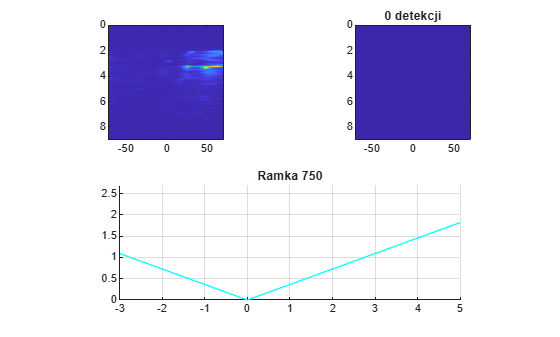

bgFilterFrameCount = 100; % @25 fps
angFftLength=64;

angleLimits=angGrid([1 end]);

tracker = radarTracker( ...
    FilterInitializationFcn=@initcvkf, ...
    ConfirmationThreshold=[7 10], ...
    AssignmentThreshold=[2 3],...
    DeletionThreshold=5, ...
    MaxNumTracks=5 ...
    );

warning('off','shared_tracking:internal:GNNTracker:MaxNumTracksReached');

colors = lines;
filterInited = false;
BG = bgFilter(zeros(rangeBins,angleBins), bgFilterFrameCount);
angFftGrid=asind((0:angFftLength-1)*2/angFftLength-1);
timesDesc = ["Tworzenie mapy", "CFAR", "Filtracja detekcji", "Śledzenie"];
times = zeros(numel(timesDesc),numFrames);
detStat = zeros(3,numFrames);

tracker({objectDetection(0,[0 0])}, 0);
trackLog = cell(numFrames,1);
targetsLog = cell(numFrames,1);

for frN=1:numFrames
    srcCube = dr.read(1, frN);
    tic;
    srcCube = iwr.arrangeVirtualDataAngleULA(srcCube);
    cube = fft(srcCube.*rngWin, [], 1) / size(srcCube, 1); % fast time FFT
    cube = cube(rngIdxs, :, :); % cut cube to rangeLimits
    cube = cube - mean(cube,3); % static clutter removal
    % cube = fftshift(fft(cube.*reshape(dopWin, 1, 1, []),[],3),3); % slow time (Doppler) FFT
    
    % angCube = fftshift(fft(cube,angFftLength,2),2); % angle FFT
    % show3D(angFftGrid, rngGrid, sum(abs(angCube),3));

    angSize = [size(cube, 1), numel(iwr.mvdrEstimator.ScanAngles)];
    angOut = zeros(angSize);
    for i = 1:angSize(1)
        angOut(i, :) = iwr.mvdrEstimator(squeeze(cube(i, :, :))').^2;
    end
    % RAM = BG.addSampleNoBg(angOut, 0.9);
    RAM = angOut;
    % mn = max([mean(RDA,"all") 0]);
    % RDA(RDA<mn)=mn;
    % data = data.^2;
    times(1,frN) = toc;
    tic;
    [dets,mask] = cfar.runCFAR2D(RAM);
    times(2,frN) = toc;
    subplot(2,2,1)
    imagesc(angGrid, rngGrid, RAM);
    pbaspect([1 1 1]);
    subplot(2,2,2)
    imagesc(angGrid, rngGrid, mask)
    detStat(1,frN) = size(dets,2);
    title(num2str(detStat(1,frN)) + " detekcji")
    pbaspect([1 1 1]);

    subplot(2,2,[3 4],"replace")
    tic
    % dets = dets(:, rngGrid(dets(1, :)) < wallCutoff(dets(2, :)));
    detStat(2,frN) = size(dets,2);
    vals=RAM(sum((dets-[0;1]).*[1;rangeBins],1)); % calculate absolute index from [xIdx;yIdx]
    [X, Y] = pol2cart(deg2rad(angGrid(dets(2, :)))+pi/2, rngGrid(dets(1, :)));
    hold off
    targets = doDbscan([X;Y;vals], 0.75, 3);
    times(3,frN) = toc;
    detStat(3,frN) = size(targets,2);

    if isEndRecording
        maxY = rngGrid(end);
    else
        maxY=wallDistance;
    end

    plotWithRadarFov(X,Y,angleLimits,cartPlotLimitsX,[0 maxY]);
    hold on
    plot(targets(1,:),targets(2,:),"o","MarkerEdgeColor","blue")
    hold off
    title("Ramka "+num2str(frN))

    tic
    numDets = size(targets,2);
    trackDets = cell(1,numDets);
    time = frN*iwr.config.FramePeriodicity*1e-3;
    for k=1:numDets
        trackDets{k} = objectDetection(time, targets(1:2,k));
    end
    [tracks,tentativeTracks,allTracks]= tracker(trackDets, time);
    times(4,frN) = toc;
    trackLog{frN} = tracks'; 
    targetsLog{frN} = targets([1 2 end],:);
    plotTrackerState(tracks,colors);

    drawnow limitrate
end

stat=nextname(data_src,"RA_stats_<01>.mat")

stat = "RA_stats_11.mat"

save(data_src+"\"+stat, "times","detStat", '-mat');

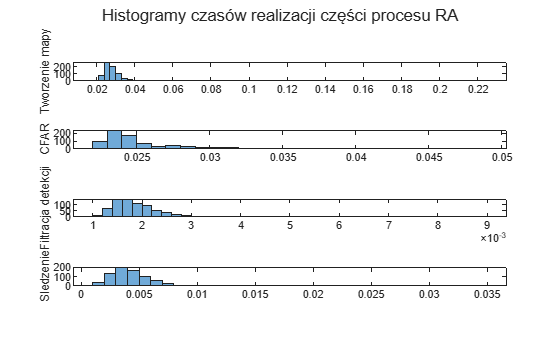

ts = numel(timesDesc);
figure(10)
clf
for n=1:ts
    subplot(ts,1,n)
    histogram(times(n,:))
    ylabel(timesDesc(n))
end
sgtitle("Histogramy czasów realizacji części procesu RA")

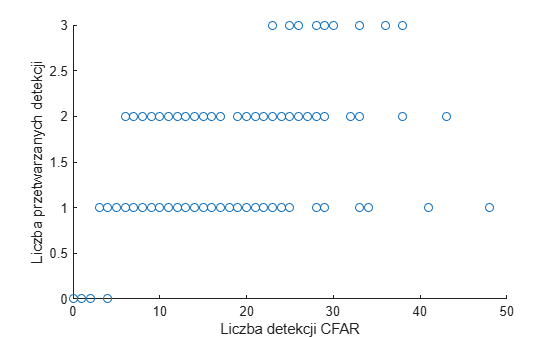


figure(11)
clf
scatter(detStat(1,:),detStat(3,:))
xlabel("Liczba detekcji CFAR")
ylabel("Liczba przetwarzanych detekcji")

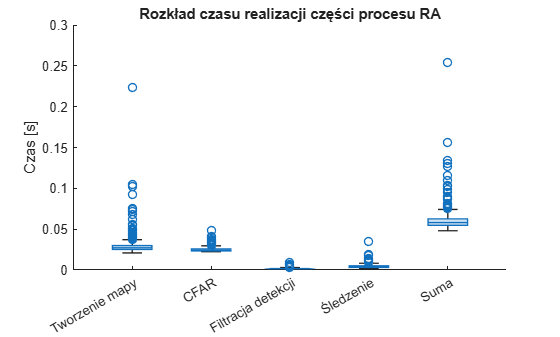


figure(12)
clf
boxchart([times;sum(times,1)]')
xticklabels([timesDesc, "Suma"])
ylabel("Czas [s]")
title("Rozkład czasu realizacji części procesu RA")

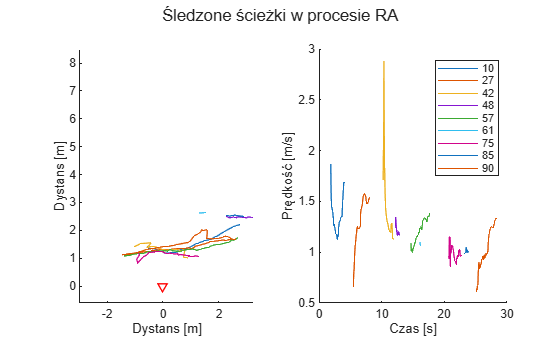

trackLogArr = [trackLog{:}];
trackLogArr = [trackLogArr(:).State; trackLogArr(:).UpdateTime; double([trackLogArr(:).TrackID])];

gndTruth = [3 3 6 6 3; 0 23 23 6 6]*0.305;

figure(20)
clf
if isEndRecording
    plot(gndTruth(1,:),gndTruth(2,:),":","Color","#aaaaaa","LineWidth",2);
    rotMat = rotz(-17);
    rotMat = rotMat(1:2,1:2);
else
    rotMat = eye(2,2);
end
ids = unique(trackLogArr(end,:));
for id=ids
    subplot(1,2,1)
    part = trackLogArr(:,trackLogArr(end,:)==id);
    XY=rotMat*part([1 3],:); % rotate according to radar position
    hold on
    plot(XY(1,:),XY(2,:)); % trail
    hold off
    subplot(1,2,2)
    hold on
    plot(part(end-1,:),hypot(part(2,:),part(4,:))); % speed
    hold off
end
subplot(1,2,1)
xlabel("Dystans [m]")
ylabel("Dystans [m]")
hold on
plot(0,0,"v",'Color','r','LineWidth',1)
ylim([0 maxY])
xlim(cartPlotLimitsX)
axis equal fill;
hold off
subplot(1,2,2)
legend(string(ids))
xlabel("Czas [s]")
ylabel("Prędkość [m/s]")
sgtitle("Śledzone ścieżki w procesie RA")

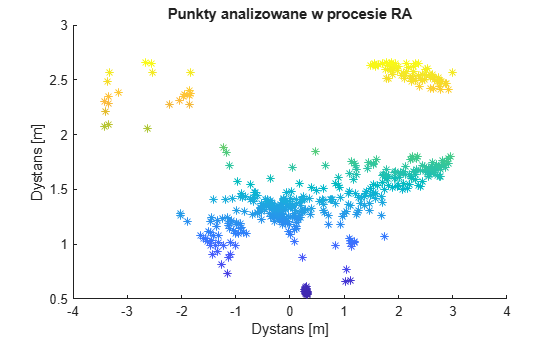


figure(21)
clf
tLog = [targetsLog{:}];
tLog(1:2, :) = rotMat * tLog(1:2, :);
hold on
scatter(tLog(1,:), tLog(2,:), 40, tLog(3,:), '*')
if isEndRecording
    plot(gndTruth(1,:),gndTruth(2,:),":","Color","#aaaaaa","LineWidth",2);
end
hold off
title("Punkty analizowane w procesie RA")
xlabel("Dystans [m]")
ylabel("Dystans [m]")

function detections = doDbscan(targets,epsilon,minpts)
    if isempty(targets)
        detections=targets;
        return
    end
    clust = dbscan(targets(1:2,:)',epsilon,minpts);
    ids = unique(clust);
    ids=ids(ids>0);
    detections = zeros(2,numel(ids));
    for i=1:numel(ids)
        part = targets(:,clust==ids(i));
        detections(:,i)=mean(part(1:2,:),2,Weights=part(end,:));
    end
end

function mask = wallMask(wallDistance,rngGrid,angGrid)
wallCutoff = wallDistance./cosd(angGrid);
[A,B]= meshgrid(wallCutoff,rngGrid);
mask=A>B;
end

function plotWithRadarFov(X,Y,angLim,xLim,yLim)
plot(X,Y, '*',"MarkerEdgeColor","r");
axis equal;
grid on
hold on
yVal=xLim.*tand(90-sort(angLim));
plot([xLim(1) 0 xLim(2)],[yVal(1) 0 yVal(2)],"Color","cyan")
xlim(xLim);
ylim(yLim);
hold off
end

function plotTrackerState(tracks,colors)
hold on
for obj=1:numel(tracks)
    coord = num2cell(tracks(obj).State([1 3 2 4]));
    color = colors(mod(tracks(obj).TrackID,size(colors,1)),:);
    plot(coord{1},coord{2},"o","MarkerFaceColor",color,"MarkerSize",10)
    quiver(coord{:},'Color',color);
end
hold off
end

function saveToGif(data_src,name)
exportgraphics(gcf,data_src+'\'+name+'.gif','Append',true);
end
